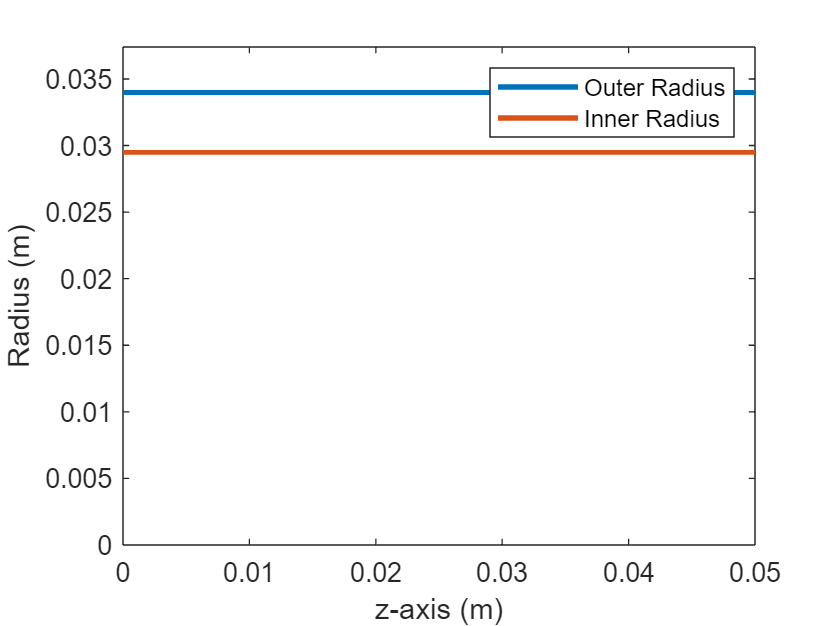

clear
% set(gcf,'color','#121212'); % turn off if using light mode, not dark mode
% https://cantera.org/install/
% https://shepherd.caltech.edu/EDL/PublicResources/sdt/
%% Requires Cantera and Shock and Detonation Toolbox (add to path) for Matlab

%% Can model inviscid flow in a RDE with momemum layer thickness and velocity power law boundary layer development

% parameters
tic
syms z

do = 0.068 ; % 0.02 % outer diameter function of z, e.g. do = 0.1*z+ 0.02
di = 0.059 ; % inner diameter function of z, 0 for hollow RDE, e.g. di =-0.1*z+ 0.01 for annular
zgeom = 0.05 ; % length of the RDE
 mx = 10000 ; % domain resolution (no. divisions)
percent_CJ = 0.60 ; % detonation waves %C-J velocity
numwaves = 5 ; % number of detonation wave/s
numInj = 72 ; % number of injector pairs
df = 1/1000 ; % fuel injector diameter (m)
dox = 1.5/1000 ; % oxidiser injector diameter (m)
mdot = 0.044 ; % mass flow rate (kg/s)
p_init = 2*10^5 ; % injected reactants pressure (Pa)
T_init = 300 ; % injected reactants temperature (K)
p_amb = 101325 ; % Ambient pressure (Pa)
q = 'H2:2.0,O2:1.0'; % set fuel and oxidiser and their amount in moles or mole fractions 
mech = 'gri30_highT.yaml'; %'gri30.yaml' ; % set reaction mechanism gri30 is only available at the moment
model = 'multicomponent' ; % set transport model 'multicomponent' or 'mixture-averaged'
deltaM = 0.0001 ; % jump across mach mach = 1 shock disconnect 
alpha = 0.0015 ; % ratio of total kinetic energy lost to rotating fluid kinetic energy for 'BLmodels 2 and 3' (experimental data suggestes somwhere between 0.00011 and 0.00774) https://doi.org/10.2514/1.B38374
Hi = 0.675     ; % incompressible shape factor for 'BLmodel 1' (reasonable value is around 1)
BLmodel = '2' ; % '1'no flow rotation, works for supersonic These dont like to go supersonic: '2' constant flow rotation '3' varying flow rotation



Ddo = double( subs(diff(do,z), z, linspace(1e-6,zgeom,mx)) );
Ddi = double( subs(diff(di,z), z, linspace(1e-6,zgeom,mx)) );
do = double( subs(do, z, linspace(1e-6,zgeom,mx)) );
di = double( subs(di, z, linspace(1e-6,zgeom,mx)) );
z = linspace(1e-6,zgeom,mx); %z-axis (m)  need a non zero starting point

if di == 0
    plot(z, do./2,'LineWidth',2)
    xlabel('z-axis (m)'); ylabel('Radius (m)'); xlim([0 zgeom]); ylim([0 (max(do)+0.1*max(do))/2 ])
    Areal = (pi/4).*(do).^2;
else
    plot(z, do./2, z, di./2,'LineWidth',2)
    xlabel('z-axis (m)'); ylabel('Radius (m)'); xlim([0 zgeom]); ylim([0 (max(do)+0.1*max(do))/2 ]); legend({'Outer Radius','Inner Radius'},'Location','northeast');
    Areal = (pi/4).*(do).^2 - (pi/4).*(di).^2;
end

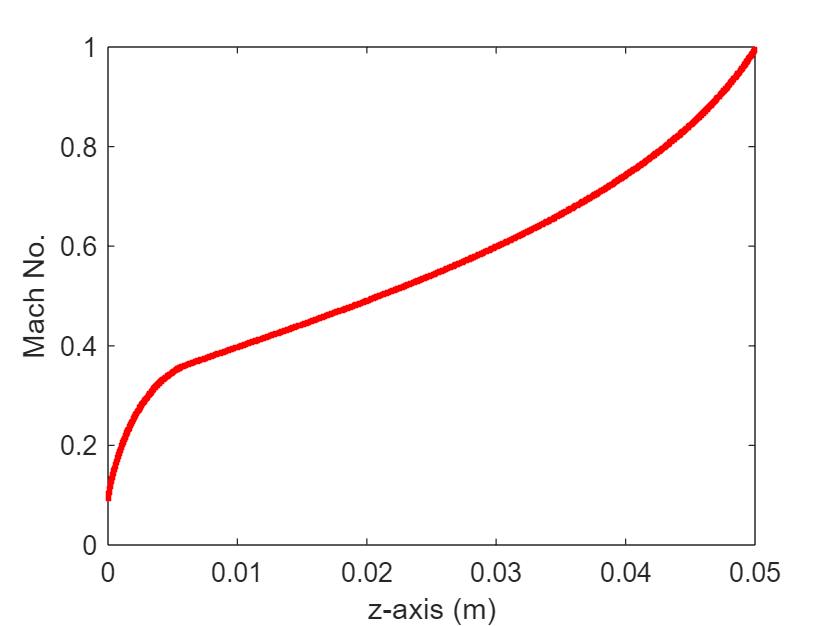


dz = zgeom/mx; % Delta(z) (m)
gas1 = Solution(mech);
Transport(gas1,model,0); % set transport model for calculating kinematic viscosity from mixture
Ru = 8.31446261815324; % universal gas constant J/(kg*mol) 
g0 = 9.8067; % gravitational acceleration const. (m/s^2)
set(gas1,'Temperature',T_init,'Pressure',p_init,'MoleFractions',q);
gamma1 = cp_mass(gas1)/cv_mass(gas1); % specific heat ratio
M1 = meanMolecularWeight(gas1) / 1000; % for reactants (kg/mol) 
h1 = enthalpy_mass(gas1); % reactant specific enthalpy (J/kg) 
Ac = pi*(do(1)^2)/4 - pi*(di(1)^2)/4; % cross sectional area (m^2)
rho_init = p_init/((Ru/M1)*T_init); % injected reactants density (kg/m^3)
u_init = (mdot/(rho_init*Ac)); % injected reactants velocity (m/s)
mu1 = viscosity(gas1); % reactant dynamic viscoosity (Pa*s)
v1 = viscosity(gas1)/rho_init; % reactant kinematic viscoosity (m^2/s)
k1 = thermalConductivity(gas1); % reactant thermal conducity(W/(m*K))
R1 = Ru / M1;% reactants specific gas constant
cp1 = cp_mass(gas1); % cp (J/(kg*k))
T0_init = T_init/((1+((gamma1-1)/2)*(u_init/sqrt(gamma1*R1*T_init))^2)^(-1)); % stagnation temperature (K)
p0_init = p_init/((1+((gamma1-1)/2)*(u_init/sqrt(gamma1*R1*T_init))^2)^((-gamma1)/(gamma1-1))); % stagnation pressure (Pa)
Mach_init = u_init/sqrt(gamma1*R1*T_init); % inital mach number ^2
dAreal = [0, diff(Areal,1)];
vw_init = sqrt((alpha*u_init^2)/(1-alpha));

%% Find CJ speed
[cj_speed] = CJspeed(p_init, T_init, q, mech);

%% Evaluate gas state
[gas] = PostShock_eq(cj_speed,p_init, T_init, q, mech);

%% Evaluate properties of gas object 
P2 = pressure(gas); % CJ pressure (Pa)
Rho2 = density(gas); % CJ density (kg/m^3)
c2_eq = soundspeed_eq(gas); % equilibrium speed of sound
gamma2 =  c2_eq*c2_eq*Rho2/P2; % equilibrium specific heat ratio
M2 = meanMolecularWeight(gas) / 1000; % for products (kg/mol) 
mu2 = viscosity(gas); % product dynamic viscoosity (Pa*s)
v2 = viscosity(gas)/Rho2; % product kinematic viscoosity (m^2/s)
k2 = thermalConductivity(gas); % product thermal conducity(W/(m*K))
cp2 = cp_mass(gas); % cp (J/(kg*k))
set(gas,'T',T_init) %heat of reaction is the difference in enthalpy at the inital reactant temperature 
h2 = enthalpy_mass(gas); % product specific enthalpy (J/kg) 
Ainj=numInj*pi*(df^2/4) + numInj*pi*(dox^2/4); % injector area (m^2)
zrc = (mdot/(rho_init*Ainj)) * ((pi*do(1))/(numwaves*percent_CJ*cj_speed)); % height of the detonation wave based on timing of injection and the detonation wave cycle time  
Q = (h1 - h2); % heat of reaction (J/kg)

D_init = 1 + 1 /( ((gamma1-1)/2)*Mach_init^2 );
R1_init = 1 - 7*(D_init-1)*( (D_init^3 /2)*log(D_init/(D_init-1))-(D_init^2 /2)-(D_init/4)-(1/6) );
R2_init = 1 - R1_init -7*(D_init-1)*( ((D_init^3.5)/2)*log((sqrt(D_init)+1)/(sqrt(D_init)-1))-(D_init^3)-(D_init^2 /3)-(D_init/5)-(1/7));

% Set inital arrays
A = zeros(size(z));
dA = zeros(size(z));
P = zeros(size(z));
rho = zeros(size(z));
T = zeros(size(z));
u = zeros(size(z));
Mach = zeros(size(z));
theta = zeros(size(z));
D = zeros(size(z));
R1 = zeros(size(z));
R2 = zeros(size(z));

% Set initial values
A(1) = Ac;
theta(1) = 1e-9;
P(1) = p_init;
rho(1) = rho_init;
T(1) = T_init;
u(1) = u_init;
Mach(1) = Mach_init;
D(1) = D_init;
R1(1) = R1_init;
R2(1) = R2_init;
vw = zeros(size(z));

switch BLmodel
    case '1' 
        alpha = zeros(size(z));
    case '2'
        vw(1) = vw_init;
        alpha = zeros(size(z)) + alpha;
    case '3'
        vw(1) = 0;
        alpha = (alpha/zgeom).*z;
    otherwise
        warning('1,2 or 3')
end


% Lambda dependant functions
Lambda = ((-z.*(z-2*zrc))/(zrc^2)) .* (z<zrc) + 1 * (z>=zrc); % combustion progress variable function (denotes the change in properties of the fluid from reactant to product)
dLambdadx = ((-2.*z+2*zrc)/(zrc^2)) .* (z<zrc) + 0 * (z>=zrc);
gamma = (1-Lambda)*gamma1 + Lambda*gamma2;
%gamma = mean(gamma) % lambda averaged gamma so it's constant
R = Ru./((1-Lambda)*M1 + Lambda*M2);
%R = mean(R) % lambda averaged R so it's constant
mu = (1-Lambda)*mu1 + Lambda*mu2;
%mu = mean(mu) % lambda averaged mu so it's constant
cp = R.*((gamma)./(gamma-1));

% Rk4 Method
for i = 2:mx
        
        if Mach(i-1) >= 1 - deltaM && Mach(i-2) <= 1 - deltaM && dAreal(i-1) == 0
            % if chamber area doesnt change but reaches choked flow due to
            % boundary layer the flow will be constant so long as chamber area doesnt change 
            rho(i-1) = rho(i-2);
            u(i-1) = u(i-2);
            A(i-1) = A(i-2);
            P(i-1) = P(i-2);
            theta(i-1) = theta(i-2);
            Mach(i-1) = Mach(i-2);
            T(i-1) = T(i-2);
            D(i-1) = D(i-2);
            R1(i-1) = R1(i-2);
            R2(i-1) = R2(i-2);

        elseif Mach(i-1) >= 1 - deltaM && Mach(i-2) <= 1 - deltaM && dAreal(i-1) <= 0
            % if flow chokes before minimum real chamber area, the mass
            % flow rate is too high as mass flow rate is a function of minimum real area
            error('mass flow rate too high, reduce mdot')
        
        elseif Mach(i-1) >= 1 - deltaM && Mach(i-2) <= 1 - deltaM && dAreal(i-1) >= 0 && z(i-1) <= zrc
            error('flow is supersonic below the height of the detonation wave, cant model this')
        
        %elseif Mach(i-1) >= 1 - deltaM && Mach(i-2) <= 1 - deltaM && dAreal(i-1) >= 0 && z(i-1) > zrc
        %elseif Mach(i-1) >= 1 - deltaM && dAreal(i-1) >= 0 && z(i-1) > zrc
            % if flow choked and real chamber area increases, flow goes
            % supersonic also remeber stagnation temperature is const.
            rho(i-1) = rho(i-2);
            u(i-1) = u(i-2);
            A(i-1) = A(i-2);
            P(i-1) = P(i-2);
            theta(i-1) = theta(i-2);
            Mach(i-1) = Mach(i-2);
            T(i-1) = T(i-2);
            D(i-1) = D(i-2);
            R1(i-1) = R1(i-2);
            R2(i-1) = R2(i-2);

            T0_t = T(i-1)/((1+((gamma(i-1)-1)/2)*(u(i-1)/sqrt(gamma(i-1)*R(i-1)*T(i-1)))^2)^(-1)); % stagnation temperature (K)
            A_t = A(i-1) / ( ( ((gamma(i-1)+1)/2)^( (-(gamma(i-1)+1))/(2*(gamma(i-1)-1)) ) ) * ( ( (1 + (gamma(i-1)-1)/2 * Mach(i-1)^2 )^( (gamma(i-1)+1)/(2*(gamma(i-1)-1)) ) ) / Mach(i-1) ) );
            A(i-1) = A_t * ( ( ((gamma(i-1)+1)/2)^( (-(gamma(i-1)+1))/(2*(gamma(i-1)-1)) ) ) * ( ( (1 + (gamma(i-1)-1)/2 * (1 + deltaM)^2 )^( (gamma(i-1)+1)/(2*(gamma(i-1)-1)) ) ) / (1 + deltaM) ) );
            T(i-1) = T0_t*((1+((gamma(i-1)-1)/2)*(1 + deltaM)^2)^(-1));
            u(i-1) = (1 + deltaM)*sqrt(gamma(i-1)*R(i-1)*T(i-1));
            rho(i-1) = mdot/(u(i-1)*A(i-1));
            P(i-1) = rho(i-1)*R(i-1)*T(i-1);
            D(i-1) = 1 + 1 /( ((gamma(i-1)-1)/2)*(1 + deltaM)^2 );
            R1(i-1) = 1 - 7*(D(i-1)-1)*( (D(i-1)^3 /2)*log(D(i-1)/(D(i-1)-1))-(D(i-1)^2 /2)-(D(i-1)/4)-(1/6) );
            R2(i-1)= 1 - R1(i-1) -7*(D(i-1)-1)*( ((D(i-1)^3.5)/2)*log((sqrt(D(i-1))+1)/(sqrt(D(i-1))-1))-(D(i-1)^3)-(D(i-1)^2 /3)-(D(i-1)/5)-(1/7));
            Mach(i-1) = (1 + deltaM);
            

            if di == 0 % hollow
                theta(i-1) = -(2*R2(i-1)*sqrt(A(i-1)) - do(i-1)*R2(i-1)*sqrt(pi))/(2*R1(i-1)*sqrt(pi));
            else       % annular
                theta(i-1) = (4*A(i-1)*R2(i-1)-pi*R2(i-1)*do(i-1)^2 + pi*R2(i-1)*di(i-1)^2)/(4*pi*R1(i-1)*(-do(i-1)+di(i-1)));
            end

            break
            
        end
        
        % k1


        k1 = EqSolv(rho(i-1),u(i-1),P(i-1),A(i-1),gamma(i-1),theta(i-1),Q,R1(i-1),R2(i-1),D(i-1),do(i-1),Lambda(i-1),dLambdadx(i-1),di(i-1),Ddo(i-1),Ddi(i-1),Hi,v1,T_init,T(i-1),vw(i-1),z(i-1),mu(i-1),BLmodel);

        drhodz_k1 = k1(1);
        dudz_k1 = k1(2);
        dAefdz_k1 = k1(3);
        dpdz_k1 = k1(4);
        dthetadz_k1 = k1(5);
        % x = [drhodz; dudz; dAefdz; dpdz; dthetadz; dR1dz; dR2dz; dDdz];

        rho_k1 = rho(i-1) + dz*(drhodz_k1/2);
        u_k1 = u(i-1) + dz*(dudz_k1/2);
        A_k1 = A(i-1) + dz*(dAefdz_k1/2);
        P_k1 = P(i-1) + dz*(dpdz_k1/2);
        theta_k1 = theta(i-1) + dz*(dthetadz_k1/2);
        Mach_k1 = u_k1/sqrt(gamma(i)*(P_k1/rho_k1));
        T_k1 = P_k1/(R(i)*rho_k1);

        D_k1 = 1 + 1 /( ((gamma(i)-1)/2)*Mach_k1^2 );
        R1_k1 = 1 - 7*(D_k1-1)*( (D_k1^3 /2)*log(D_k1/(D_k1-1))-(D_k1^2 /2)-(D_k1/4)-(1/6) );
        R2_k1 = 1 - R1_k1 -7*(D_k1-1)*( ((D_k1^3.5)/2)*log((sqrt(D_k1)+1)/(sqrt(D_k1)-1))-(D_k1^3)-(D_k1^2 /3)-(D_k1/5)-(1/7));

        vw_k1 = sqrt((alpha(i)*u_k1^2)/(1-alpha(i)));


        % k2


        k2 = EqSolv(rho_k1,u_k1,P_k1,A_k1,gamma(i-1),theta_k1,Q,R1_k1,R2_k1,D_k1,do(i-1),Lambda(i-1),dLambdadx(i-1),di(i-1),Ddo(i-1),Ddi(i-1),Hi,v1,T_init,T_k1,vw_k1,z(i-1),mu(i-1),BLmodel);

        drhodz_k2 = k2(1);
        dudz_k2 = k2(2);
        dAefdz_k2 = k2(3);
        dpdz_k2 = k2(4);
        dthetadz_k2 = k2(5);

        rho_k2 = rho(i-1) + dz*(drhodz_k2/2);
        u_k2 = u(i-1) + dz*(dudz_k2/2);
        A_k2 = A(i-1) + dz*(dAefdz_k2/2);
        P_k2 = P(i-1) + dz*(dpdz_k2/2);
        theta_k2 = theta(i-1) + dz*(dthetadz_k2/2);
        Mach_k2 = u_k2/sqrt(gamma(i)*(P_k2/rho_k2));
        T_k2 = P_k2/(R(i)*rho_k2);

        D_k2 = 1 + 1 /( ((gamma(i)-1)/2)*Mach_k2^2 );
        R1_k2 = 1 - 7*(D_k2-1)*( (D_k2^3 /2)*log(D_k2/(D_k2-1))-(D_k2^2 /2)-(D_k2/4)-(1/6) );
        R2_k2 = 1 - R1_k2 -7*(D_k2-1)*( ((D_k2^3.5)/2)*log((sqrt(D_k2)+1)/(sqrt(D_k2)-1))-(D_k2^3)-(D_k2^2 /3)-(D_k2/5)-(1/7));

        vw_k2 = sqrt((alpha(i)*u_k2^2)/(1-alpha(i)));

        % k3


        k3 = EqSolv(rho_k2,u_k2,P_k2,A_k2,gamma(i-1),theta_k2,Q,R1_k2,R2_k2,D_k2,do(i-1),Lambda(i-1),dLambdadx(i-1),di(i-1),Ddo(i-1),Ddi(i-1),Hi,v1,T_init,T_k2,vw_k2,z(i-1),mu(i-1),BLmodel);

        drhodz_k3 = k3(1);
        dudz_k3 = k3(2);
        dAefdz_k3 = k3(3);
        dpdz_k3 = k3(4);
        dthetadz_k3 = k3(5);

        rho_k3 = rho(i-1) + dz*(drhodz_k3);
        u_k3 = u(i-1) + dz*(dudz_k3);
        A_k3 = A(i-1) + dz*(dAefdz_k3);
        P_k3 = P(i-1) + dz*(dpdz_k3);
        theta_k3 = theta(i-1) + dz*(dthetadz_k3);
        Mach_k3 = u_k3/sqrt(gamma(i)*(P_k3/rho_k3));
        T_k3 = P_k3/(R(i)*rho_k3);

        D_k3 = 1 + 1 /( ((gamma(i)-1)/2)*Mach_k3^2 );
        R1_k3 = 1 - 7*(D_k3-1)*( (D_k3^3 /2)*log(D_k3/(D_k3-1))-(D_k3^2 /2)-(D_k3/4)-(1/6) );
        R2_k3 = 1 - R1_k3 -7*(D_k3-1)*( ((D_k3^3.5)/2)*log((sqrt(D_k3)+1)/(sqrt(D_k3)-1))-(D_k3^3)-(D_k3^2 /3)-(D_k3/5)-(1/7));

        vw_k3 = sqrt((alpha(i)*u_k3^2)/(1-alpha(i)));

        % k4


        k4 = EqSolv(rho_k3,u_k3,P_k3,A_k3,gamma(i-1),theta_k3,Q,R1_k3,R2_k3,D_k3,do(i-1),Lambda(i-1),dLambdadx(i-1),di(i-1),Ddo(i-1),Ddi(i-1),Hi,v1,T_init,T_k3,vw_k3,z(i-1),mu(i-1),BLmodel);

        drhodz_k4 = k4(1);
        dudz_k4 = k4(2);
        dAefdz_k4 = k4(3);
        dpdz_k4 = k4(4);
        dthetadz_k4 = k4(5);

        %rho_k4 = rho(i-1) + dz*(drhodz_k4);
        %u_k4 = u(i-1) + dz*(dudz_k4);
        %A_k4 = A(i-1) + dz*(dAefdz_k4);
        %P_k4 = P(i-1) + dz*(dpdz_k4);
        %theta_k4 = theta(i-1) + dz*(dthetadz_k4);

        rho(i) = rho(i-1) + (dz/6)*(drhodz_k1 + 2*drhodz_k2 + 2*drhodz_k3 + drhodz_k4);
        u(i) = u(i-1) + (dz/6)*(dudz_k1 + 2*dudz_k2 + 2*dudz_k3 + dudz_k4);
        A(i) = A(i-1) + (dz/6)*(dAefdz_k1 + 2*dAefdz_k2 + 2*dAefdz_k3 + dAefdz_k4);
        P(i) = P(i-1) + (dz/6)*(dpdz_k1 + 2*dpdz_k2 + 2*dpdz_k3 + dpdz_k4);
        theta(i) = theta(i-1) + (dz/6)*(dthetadz_k1 + 2*dthetadz_k2 + 2*dthetadz_k3 + dthetadz_k4);
        Mach(i) = u(i)/sqrt(gamma(i)*(P(i)/rho(i)));
        T(i) = P(i)/(R(i)*rho(i));

        D(i) = 1 + 1 /( ((gamma(i)-1)/2)*Mach(i)^2 );
        R1(i) = 1 - 7*(D(i)-1)*( (D(i)^3 /2)*log(D(i)/(D(i)-1))-(D(i)^2 /2)-(D(i)/4)-(1/6) );
        R2(i) = 1 - R1(i) -7*(D(i)-1)*( ((D(i)^3.5)/2)*log((sqrt(D(i))+1)/(sqrt(D(i))-1))-(D(i)^3)-(D(i)^2 /3)-(D(i)/5)-(1/7));

        vw(i) = sqrt((alpha(i)*u(i)^2)/(1-alpha(i)));
        

end


if Mach(end) == 0

    for k = i:mx
        % let theta R1 R2 be constant for supersonic flow as an assumption
        % to just start letting us model supersonic flow, will change so
        % they are variable and solved as a nonlinear set of equations
        % later
        dM2 = (Mach(k-1)^2)* ( (-2*(1 + ((gamma2-1)/2) * Mach(k-1)^2 ) ) / (1-Mach(k-1)^2)) * (dAreal(k-1)/A(k-1));
        Mach(k) = sqrt(Mach(k-1)^2 + dM2) ;
        A(k) = A(k-1) + dAreal(k-1);
        dMach2Mach2 = dM2/(Mach(k-1));
        
        
        %calculate the rest of the values
        dTempTemp   = dTT(Mach(k-1)^2,gamma(k-1),dMach2Mach2,0);
        T(k)        = T(k-1) + T(k-1)*dTempTemp;
        dVeloVelo   = dVV(dMach2Mach2,dTempTemp);
        u(k)        = u(k-1) + u(k-1)*dVeloVelo;
        drhorho     = drr(dVeloVelo,dAreal(k-1)/A(k-1));
        rho(k)      = rho(k-1) + rho(k-1)*drhorho;
        dprespres   = dpp(drhorho,dTempTemp);
        P(k)        = P(k-1) + P(k-1)*dprespres;
        
        theta(k) = theta(k-1);
        D(k) = D(k-1);
        R1(k) = R1(k-1);
        R2(k) = R2(k-1);
    end
end

%% Thrust and Isp
thrust = mdot*u(end) + (P(end) - p_amb)*Areal(end); % thrust (N)
Isp = thrust / (mdot*g0);

%% Plotting

plot(z,Mach,'r--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Mach No.')

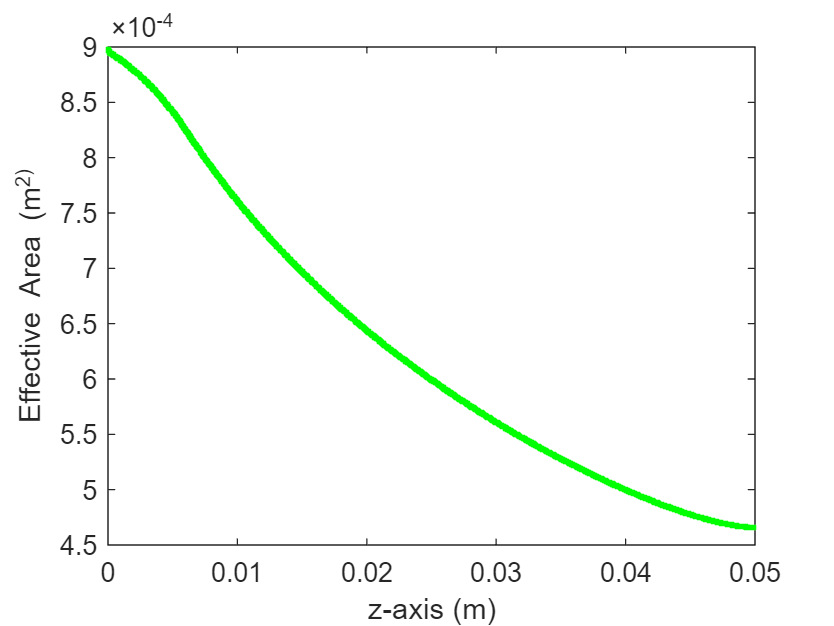


plot(z,A,'g--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Effective Area (m^2)')

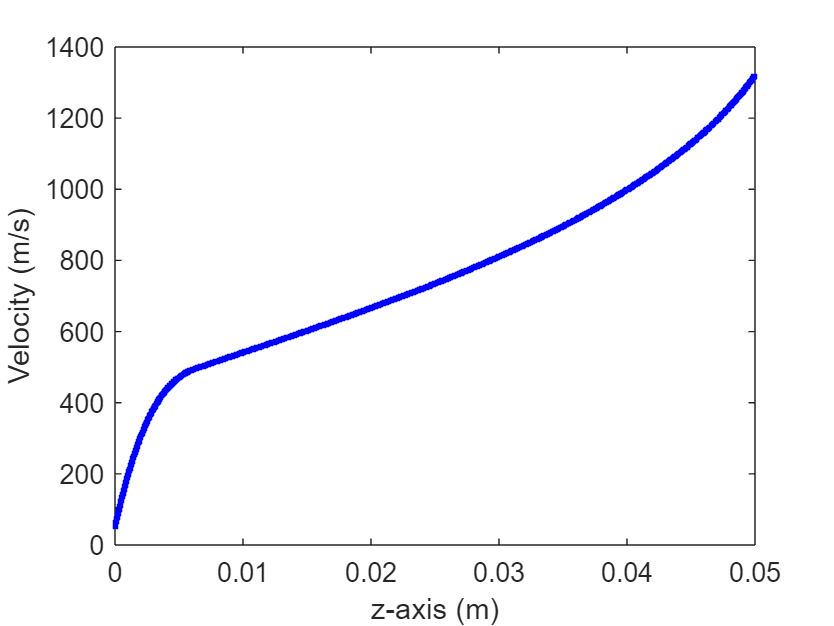


plot(z,u,'b--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Velocity (m/s)')

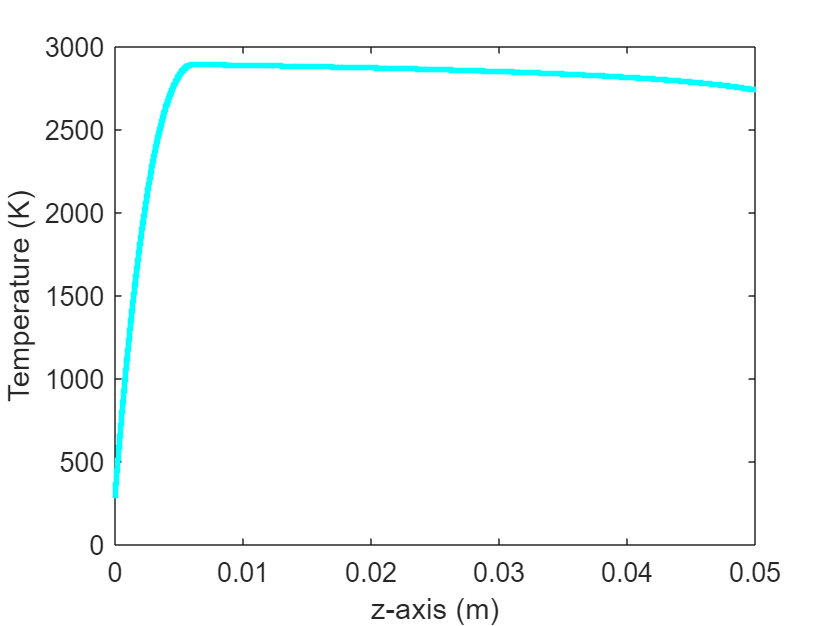


plot(z,T,'c--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Temperature (K)')

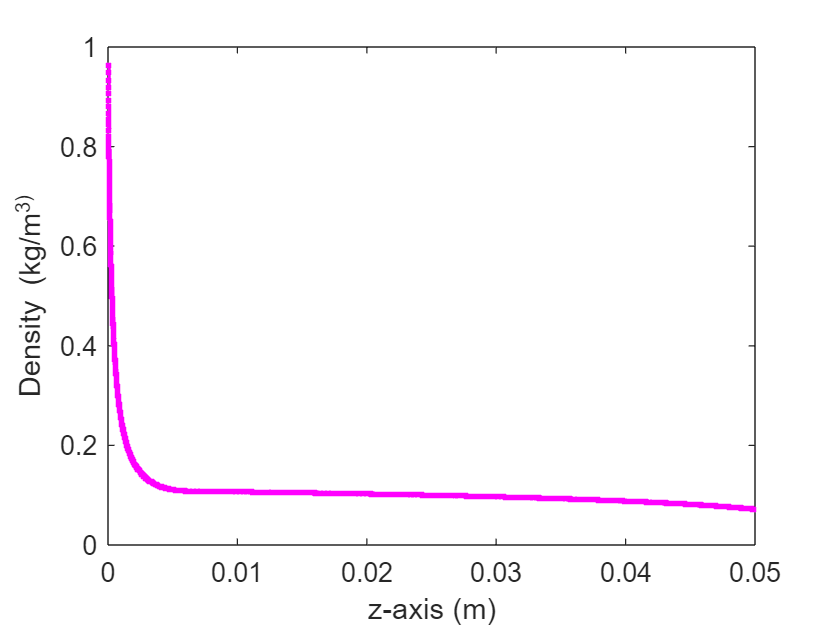


plot(z,rho,'m--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Density (kg/m^3)')

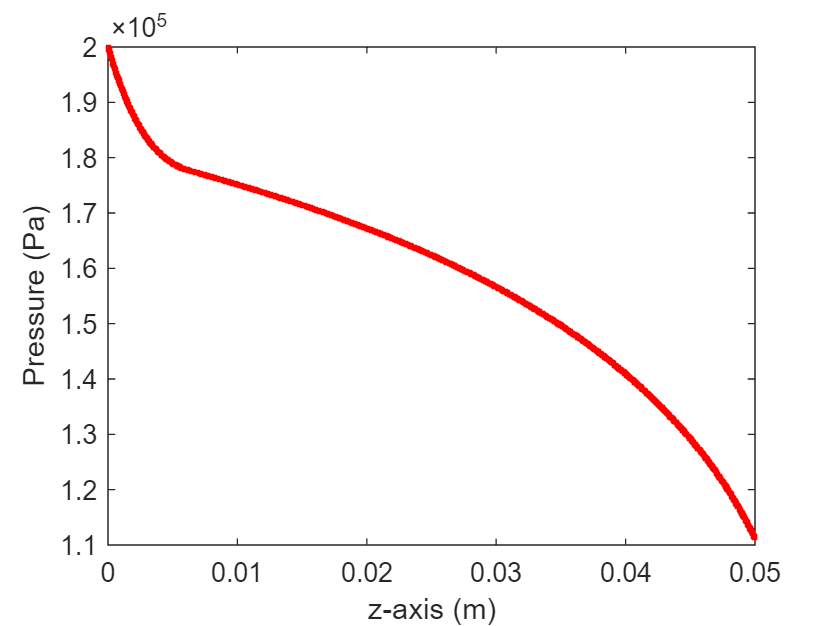


plot(z,P,'r--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Pressure (Pa)')

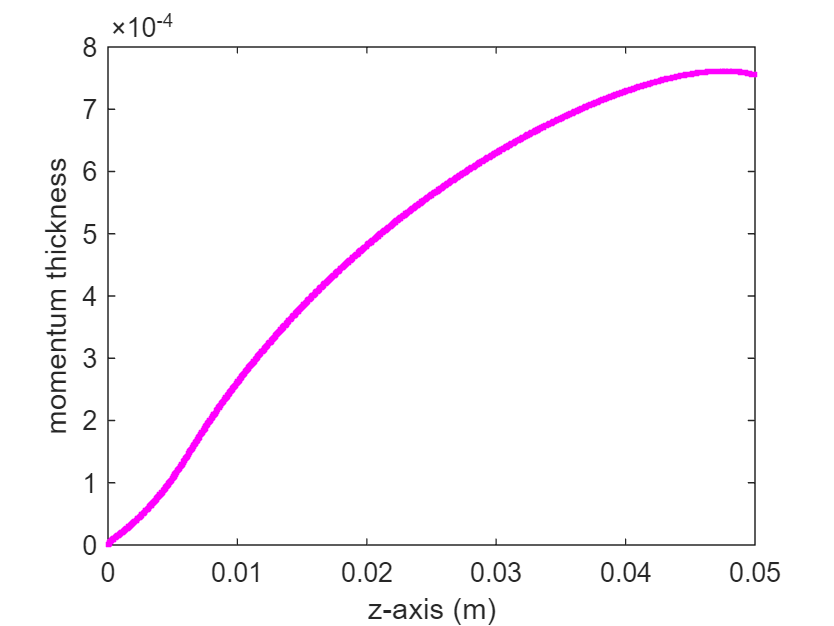


plot(z,theta,'m--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('momentum thickness')

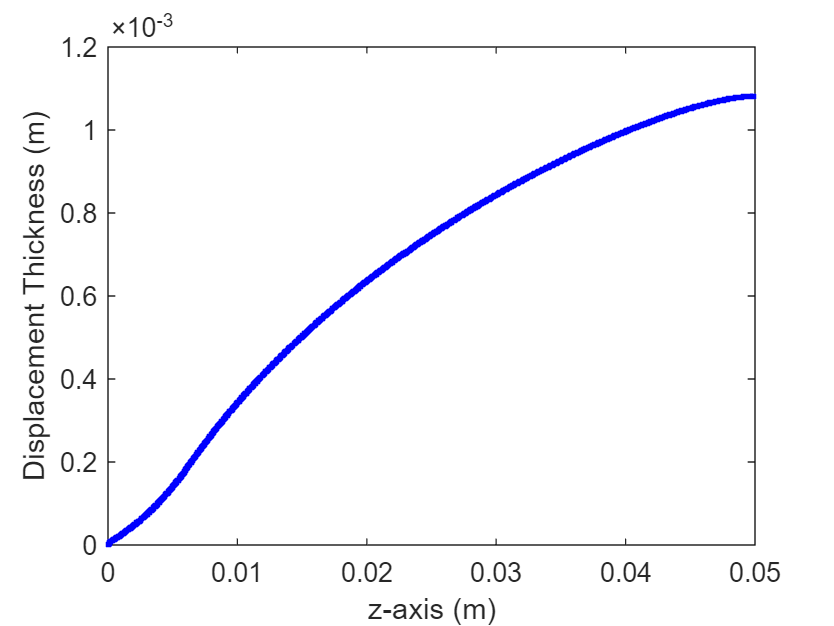


plot(z,theta.*(R1./R2),'b--.','LineWidth',2)
xlabel('z-axis (m)')
ylabel('Displacement Thickness (m)')


fprintf('The thrust is: %.2f N.\n', thrust);

The thrust is: 66.95 N.


fprintf('The speicific impulse is: %.2f s.\n', Isp);

The speicific impulse is: 155.15 s.



toc

Elapsed time is 16.119798 seconds.


function out = EqSolv(rho,u,p,Aef,gamma,theta,Q,R1,R2,D,d_o,lambda,dlambdadz,d_i,ddodz,ddidz,Hi,vref,Tref,T,vw,z,mu,BLmodel)

    %syms drhodz dudz dpdz dAefdz dthetadz dR1dz dR2dz dDdz
    
    if d_i > 0 % annular RDE

        switch BLmodel
            case '1'
                A = [1/rho, 1/u, 1/Aef, (0), (0), (0), (0), (0); (0), u, (0), 1/rho, (0), (0), (0), (0); Aef*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))) - (Aef*gamma*p*u)/(rho*(gamma - 1)), Aef*rho*u^2 + Aef*rho*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), rho*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), (Aef*gamma*u)/(gamma - 1), (0), (0), (0), (0); (0), (0), (1), (0), ((pi)*R1*(d_i + (2*R1*theta)/R2))/R2 + ((pi)*R1*(d_o - (2*R1*theta)/R2))/R2, ((pi)*theta*(d_i + (2*R1*theta)/R2))/R2 + ((pi)*theta*(d_o - (2*R1*theta)/R2))/R2, - ((pi)*R1*theta*(d_i + (2*R1*theta)/R2))/R2^2 - ((pi)*R1*theta*(d_o - (2*R1*theta)/R2))/R2^2, (0); (gamma*p)/(rho^2*u^2*(gamma/2 - (1/2))), (2*gamma*p)/(rho*u^3*(gamma/2 - (1/2))), (0), -gamma/(rho*u^2*(gamma/2 - (1/2))), (0), (0), (0), (1); (0), (0), (0), (0), (0), (1), (0), (7*D^(3)*log(D/(D - (1))))/2 - ((7)*D)/4 - (7*D^(2))/2 - ((7)*D - 7)*(D - (3*D^(2)*log(D/(D - (1))))/2 - (D^(2)*(1/(D - (1)) - D/(D - (1))^(2))*(D - (1)))/2 + (1/4)) - (7/6); (0), (0), (0), (0), (0), (1), (1), (7*D^(7/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/2 - ((7)*D)/5 - ((7)*D - 7)*(((2)*D)/3 - (7*D^(5/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/4 + 3*D^(2) - (D^(7/2)*(sqrt(D) - (1))*(1/((2)*sqrt(D)*(sqrt(D) - (1))) - (sqrt(D) + (1))/(2*sqrt(D)*(sqrt(D) - (1))^(2))))/((2)*sqrt(D) + 2) + (1/5)) - (7*D^(2))/3 - 7*D^(3) - 1; theta/rho, (2*theta)/u + (R1*theta)/(R2*u), (0), (0), (1), (0), (0), (0)];
                B = [(0); (0); Aef*Q*dlambdadz*rho*u; ((pi)*ddodz*(d_o - (2*R1*theta)/R2))/2 - ((pi)*ddidz*(d_i + (2*R1*theta)/R2))/2; (0); (0); (0); (123*exp((-(1561*Hi)/1000))*(T/Tref)^(317/250))/(1000*((theta*u)/vref)^(67/250))];
        
            case {'2','3'}
                A = [1/rho, 1/u, 1/Aef, (0), (0), (0), (0), (0); (0), u, (0), 1/rho, (0), (0), (0), (0); Aef*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))) - (Aef*gamma*p*u)/(rho*(gamma - 1)), Aef*rho*u^2 + Aef*rho*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), rho*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), (Aef*gamma*u)/(gamma - 1), (0), (0), (0), (0); (0), (0), (1), (0), ((pi)*R1*(d_i + (2*R1*theta)/R2))/R2 + ((pi)*R1*(d_o - (2*R1*theta)/R2))/R2, ((pi)*theta*(d_i + (2*R1*theta)/R2))/R2 + ((pi)*theta*(d_o - (2*R1*theta)/R2))/R2, - ((pi)*R1*theta*(d_i + (2*R1*theta)/R2))/R2^2 - ((pi)*R1*theta*(d_o - (2*R1*theta)/R2))/R2^2, (0); (gamma*p)/(rho^2*u^2*(gamma/2 - (1/2))), (2*gamma*p)/(rho*u^3*(gamma/2 - (1/2))), (0), -gamma/(rho*u^2*(gamma/2 - (1/2))), (0), (0), (0), (1); (0), (0), (0), (0), (0), (1), (0), (7*D^(3)*log(D/(D - (1))))/2 - ((7)*D)/4 - (7*D^(2))/2 - ((7)*D - 7)*(D - (3*D^(2)*log(D/(D - (1))))/2 - (D^(2)*(1/(D - (1)) - D/(D - (1))^(2))*(D - (1)))/2 + (1/4)) - (7/6); (0), (0), (0), (0), (0), (1), (1), (7*D^(7/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/2 - ((7)*D)/5 - ((7)*D - 7)*(((2)*D)/3 - (7*D^(5/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/4 + 3*D^(2) - (D^(7/2)*(sqrt(D) - (1))*(1/((2)*sqrt(D)*(sqrt(D) - (1))) - (sqrt(D) + (1))/(2*sqrt(D)*(sqrt(D) - (1))^(2))))/((2)*sqrt(D) + 2) + (1/5)) - (7*D^(2))/3 - 7*D^(3) - 1; theta/rho, (2*theta)/u + (R1*theta)/(R2*u), (0), (0), (1), (0), (0), (0)];
                B = [(0); (0); Aef*Q*dlambdadz*rho*u; ((pi)*ddodz*(d_o - (2*R1*theta)/R2))/2 - ((pi)*ddidz*(d_i + (2*R1*theta)/R2))/2; (0); (0); (0); 131/(10000*((rho*u*z)/mu)^(1/7)) + (vw*((rho*u^2*(gamma/2 - (1/2)))/(gamma*p) + 1)^(1/(gamma - 1)))/u];
        
            otherwise
                warning('1,2 or 3')
        end

    else % hollow RDE 

        switch BLmodel
            case '1' 
                A = [1/rho, 1/u, 1/Aef, (0), (0), (0), (0), (0); (0), u, (0), 1/rho, (0), (0), (0), (0); Aef*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))) - (Aef*gamma*p*u)/(rho*(gamma - 1)), Aef*rho*u^2 + Aef*rho*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), rho*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), (Aef*gamma*u)/(gamma - 1), (0), (0), (0), (0); (0), (0), (1), (0), ((pi)*R1*(d_o - (2*R1*theta)/R2))/R2, ((pi)*theta*(d_o - (2*R1*theta)/R2))/R2, -((pi)*R1*theta*(d_o - (2*R1*theta)/R2))/R2^2, (0); (gamma*p)/(rho^2*u^2*(gamma/2 - (1/2))), (2*gamma*p)/(rho*u^3*(gamma/2 - (1/2))), (0), -gamma/(rho*u^2*(gamma/2 - (1/2))), (0), (0), (0), (1); (0), (0), (0), (0), (0), (1), (0), (7*D^(3)*log(D/(D - (1))))/2 - ((7)*D)/4 - (7*D^(2))/2 - ((7)*D - 7)*(D - (3*D^(2)*log(D/(D - (1))))/2 - (D^(2)*(1/(D - (1)) - D/(D - (1))^(2))*(D - (1)))/2 + (1/4)) - (7/6); (0), (0), (0), (0), (0), (1), (1), (7*D^(7/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/2 - ((7)*D)/5 - ((7)*D - 7)*(((2)*D)/3 - (7*D^(5/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/4 + 3*D^(2) - (D^(7/2)*(sqrt(D) - (1))*(1/((2)*sqrt(D)*(sqrt(D) - (1))) - (sqrt(D) + (1))/(2*sqrt(D)*(sqrt(D) - (1))^(2))))/((2)*sqrt(D) + 2) + (1/5)) - (7*D^(2))/3 - 7*D^(3) - 1; theta/rho, (2*theta)/u + (R1*theta)/(R2*u), (0), (0), (1), (0), (0), (0)];
                B = [(0); (0); Aef*Q*dlambdadz*rho*u; ((pi)*ddodz*(d_o - (2*R1*theta)/R2))/2; (0); (0); (0); (123*exp((-(1561*Hi)/1000))*(T/Tref)^(317/250))/(1000*((theta*u)/vref)^(67/250))];
        
            case {'2','3'}
                A = [1/rho, 1/u, 1/Aef, (0), (0), (0), (0), (0); (0), u, (0), 1/rho, (0), (0), (0), (0); Aef*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))) - (Aef*gamma*p*u)/(rho*(gamma - 1)), Aef*rho*u^2 + Aef*rho*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), rho*u*(u^2/2 - Q*lambda + (gamma*p)/(rho*(gamma - 1))), (Aef*gamma*u)/(gamma - 1), (0), (0), (0), (0); (0), (0), (1), (0), ((pi)*R1*(d_o - (2*R1*theta)/R2))/R2, ((pi)*theta*(d_o - (2*R1*theta)/R2))/R2, -((pi)*R1*theta*(d_o - (2*R1*theta)/R2))/R2^2, (0); (gamma*p)/(rho^2*u^2*(gamma/2 - (1/2))), (2*gamma*p)/(rho*u^3*(gamma/2 - (1/2))), (0), -gamma/(rho*u^2*(gamma/2 - (1/2))), (0), (0), (0), (1); (0), (0), (0), (0), (0), (1), (0), (7*D^(3)*log(D/(D - (1))))/2 - ((7)*D)/4 - (7*D^(2))/2 - ((7)*D - 7)*(D - (3*D^(2)*log(D/(D - (1))))/2 - (D^(2)*(1/(D - (1)) - D/(D - (1))^(2))*(D - (1)))/2 + (1/4)) - (7/6); (0), (0), (0), (0), (0), (1), (1), (7*D^(7/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/2 - ((7)*D)/5 - ((7)*D - 7)*(((2)*D)/3 - (7*D^(5/2)*log((sqrt(D) + (1))/(sqrt(D) - (1))))/4 + 3*D^(2) - (D^(7/2)*(sqrt(D) - (1))*(1/((2)*sqrt(D)*(sqrt(D) - (1))) - (sqrt(D) + (1))/(2*sqrt(D)*(sqrt(D) - (1))^(2))))/((2)*sqrt(D) + 2) + (1/5)) - (7*D^(2))/3 - 7*D^(3) - 1; theta/rho, (2*theta)/u + (R1*theta)/(R2*u), (0), (0), (1), (0), (0), (0)];
                B = [(0); (0); Aef*Q*dlambdadz*rho*u; ((pi)*ddodz*(d_o - (2*R1*theta)/R2))/2; (0); (0); (0); 131/(10000*((rho*u*z)/mu)^(1/7)) + (vw*((rho*u^2*(gamma/2 - (1/2)))/(gamma*p) + 1)^(1/(gamma - 1)))/u];
     
            otherwise
                warning('1,2 or 3')
        end

    end
    % from https://stackoverflow.com/questions/32711920/what-is-benefit-to-use-svd-for-solving-ax-b
    % singluar value decomposition method for solving linear system as it's
    % good for ill conditioned matrixes
    [U,S,V] = svd(A);
    out = V*(diag(diag(S).^-1)*(U.'*B));

end



function out = dTT(Mach2,gamma,dMach2Mach2,dT0T0)
    out = dT0T0 - ((((gamma-1)/2)*Mach2) / (1+((gamma-1)/2)*Mach2))*dMach2Mach2;
end

function out = dVV(dMach2Mach2,dTempTemp)
    out = 0.5*(dMach2Mach2 + dTempTemp);
end

function out = drr(dVeloVelo,dAA)
    out = - dAA - dVeloVelo;
end

function out = dpp(drhorho,dTempTemp)
    out = drhorho + dTempTemp;
end
